## **JULIO CESAR GARCIA RIBEIRO                                      RA: 1994484**

#### **ATIVIDADE PRÁTICA 5**

**Sinal original e sinal com adição do ruído:**

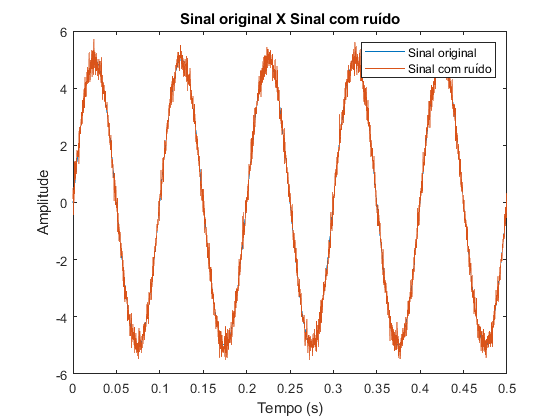

Fs = 5000;
t = 0:1/Fs:0.5;

y = 5*sin(20*pi*t);    % Sinal sem ruído
n = 0.25*randn(1, length(y));    % Ruído
yr = y + n;     % Sinal com ruído

figure;
plot(t, y);
hold on;
plot(t, yr);
title('Sinal original X Sinal com ruído'); xlabel('Tempo (s)'); ylabel('Amplitude');
legend('Sinal original', 'Sinal com ruído');

Comparação no domínio do tempo do sinal original e do sinal adicionado de ruído.

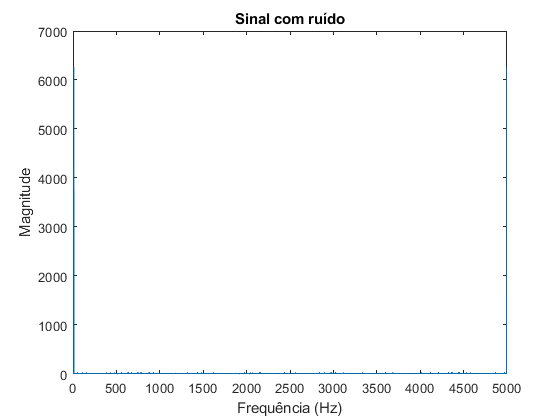

fourier_yr = fft(yr);
f = linspace(0, Fs, length(yr));

figure;
plot(f, abs(fourier_yr));
title('Sinal com ruído'); xlabel('Frequência (Hz)'); ylabel('Magnitude');

Sinal com ruído representado no domínio da frequência.

Se consegue perceber pequenas componentes espalhadas por todo o espectro de frequência.

**Filtragem do sinal utilizando filtro média móvel de ordem 10:**

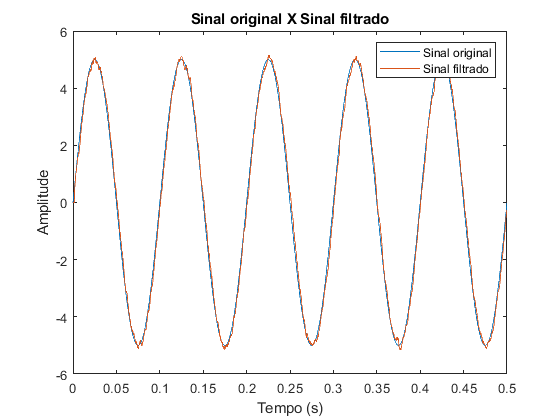

% 1 - a
N = 10;     % Ordem do filtro
for i = N:length(yr)    % Percorre o vetor a partir do índice da ordem do vetor
    result = 0;     % variável auxiliar
    for j = 0:(N-1)     % Laço auxiliar para calcular os 10 valores para fazer a média
        result = result + yr(i-j);
    end
    result = result/N;  % Divide a soma dos sinais pela quantidade de amostras (ordem do filtro)
    yf(i) = result;     % Salva no vetor de sinal filtrado
end

figure;
plot(t, y);
hold on;
plot(t, yf);
title('Sinal original X Sinal filtrado'); xlabel('Tempo (s)'); ylabel('Amplitude');
legend('Sinal original', 'Sinal filtrado');

Comparação no domínio do tempo dos sinais filtrados.

Se percebe que a curva do sinal filtrado se aproxima do sinal original.

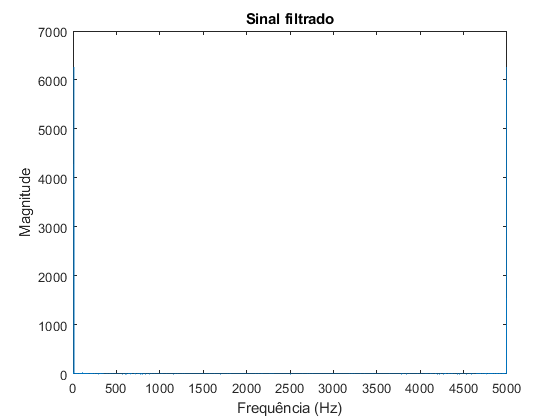

fourier_yf = fft(yf);
f = linspace(0, Fs, length(yf));

figure;
plot(f, abs(fourier_yf));
title('Sinal filtrado'); xlabel('Frequência (Hz)'); ylabel('Magnitude');

Sinal com ruído representado no domínio da frequência.

Em comparação a resposta em frequência do sinal com ruído apresentada anterioemente, se percebe atenuação nas frequência do ruído.

**Comparação de filtragem do sinal utilizando filtro média móvel de ordem 5, 10 e 20:**

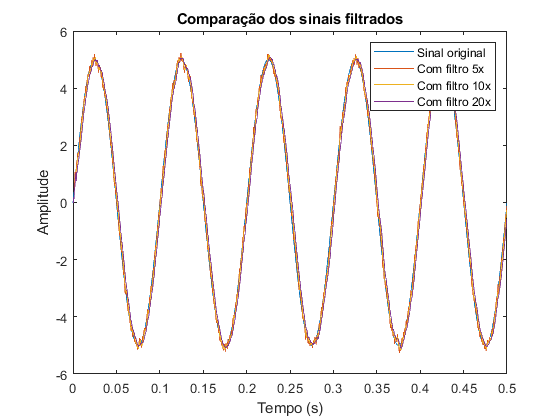

% 1 - b
figure;
plot(t, y);
hold on;

N = 5;
for i = N:length(yr)
    result = 0;
    for j = 0:(N-1)
        result = result + yr(i-j);
    end
    result = result/N;
    yf(i) = result;
end

plot(t, yf);
hold on;

N = 10;
for i = N:length(yr)
    result = 0;
    for j = 0:(N-1)
        result = result + yr(i-j);
    end
    result = result/N;
    yf(i) = result;
end

plot(t, yf);
hold on;

N = 20;
for i = N:length(yr)
    result = 0;
    for j = 0:(N-1)
        result = result + yr(i-j);
    end
    result = result/N;
    yf(i) = result;
end

plot(t, yf);
title('Comparação dos sinais filtrados'); xlabel('Tempo (s)'); ylabel('Amplitude');
legend('Sinal original', 'Com filtro 5x', 'Com filtro 10x', 'Com filtro 20x');

Comparação no domínio do tempo dos sinais filtrados.

Quanto maior é a ordem do filtro, mais próxima é a sua semelhança ao sinal original. Se percebe que com ordem 20, o sinal tem grande semelhança ao sinal original. Se observa também que os sinais com ordem menores (5 e 10) tem aproximações piores. Contudo, quanto maior é a ordem do filtro, mais difícil é a sua implementação, por depender do hardware do controlador que se vai utilizar. 

**Sinal de áudio para ser filtrado:**

Como o aplicativo gerador de funções do celular suporta apenas 2 canais por vez, e o fato de que o microfone utilizado não capturar a frequencia de 29Hz, se realizou um código para gerar a função necessária que será filtrada e executada posteriormente.

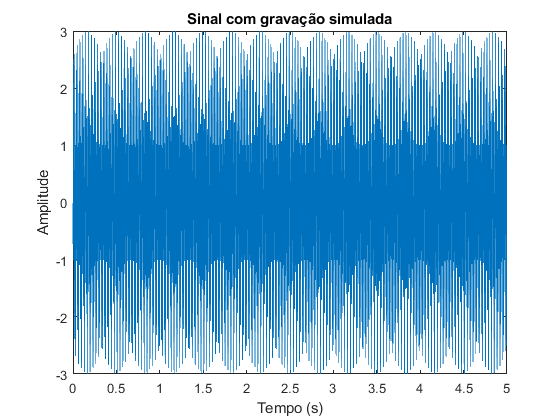

% 2 - a
Fs = 22050;
time = 5;


% Deixo aqui o código da captura do audio comentada -> não foi uma boa
% captura, meu microfone não conseguia capturar a frequencia de 29Hz (meu
% dia de nascimento). Gerei o sinal e reproduzo ele com a função "sound"
% posteriormente

%recording = audiorecorder(Fs, 16, 1);
%disp('Recording');
%recordblocking(recording, time);
%disp('End of recording');
%sa = getaudiodata(recording);


t = 0:1/Fs:time;
sa = sin(2*pi*29*t) + sin(2*pi*90*t) + sin(2*pi*2008*t);

figure;
plot(t, sa);
title('Sinal com gravação simulada'); xlabel('Tempo (s)'); ylabel('Amplitude');

Sinal gerando representado no domínio do tempo.

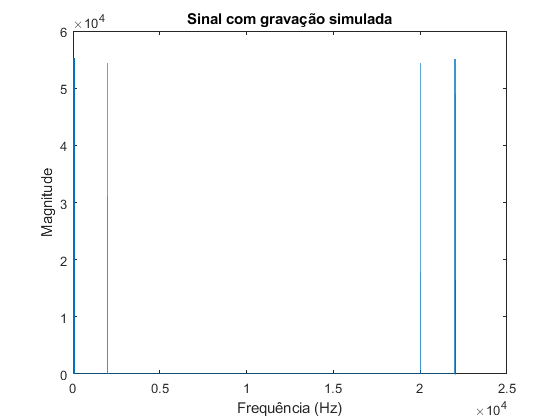

fourier_sa = fft(sa);
f = linspace(0, Fs, length(fourier_sa));

figure;
plot(f, abs(fourier_sa));
title('Sinal com gravação simulada'); xlabel('Frequência (Hz)'); ylabel('Magnitude');

Sinal gerando representado no domínio da frequência.

Se percebe as 3 componentes em 29Hz, 90Hz e 2008Hz.

**Projetos de filtro FIR passa baixa e passa alta para o sinal gerado:**

Para se projetar os filtros FIR passa alta e passa baixa se utilzou a ferramenta Filter Deigner. Ambos os filtros foram projetados utilizando o método Kaiser, com ordem mínima gerada pelo aplicativo. 

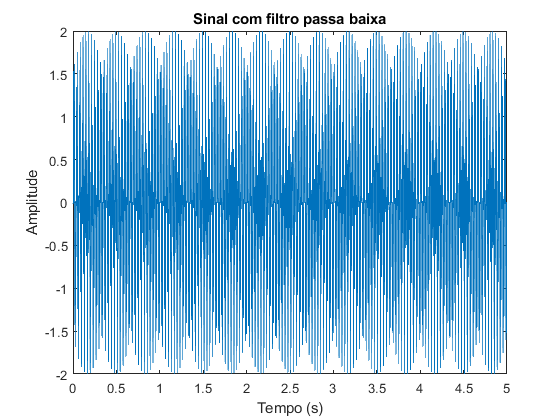

% 2 - b/c
sa_lowpass = filter(lowpass_kaiser, sa);
%sound(sa_lowpass, Fs)

figure;
plot(t, sa_lowpass);
title('Sinal com filtro passa baixa'); xlabel('Tempo (s)'); ylabel('Amplitude');

Sinal filtrado com filtro passa baixa representado no domínio do tempo.

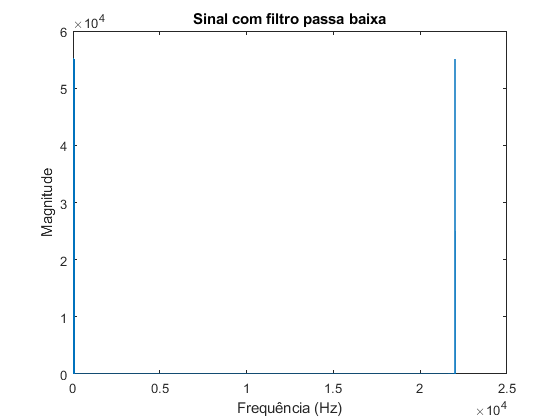

figure;
plot(f, abs(fft(sa_lowpass)));
title('Sinal com filtro passa baixa'); xlabel('Frequência (Hz)'); ylabel('Magnitude');

Sinal filtrado com filtro passa baixa representado no domínio da frequência.

As frequências de passagem e atenuação para o caso do filtro passa baixa foram, respectivamente: 100Hz e 1500Hz.

O filtro passa baixa gerada é de ordem 80 e consegue atenuar com efeciência a frequência de 2008Hz.

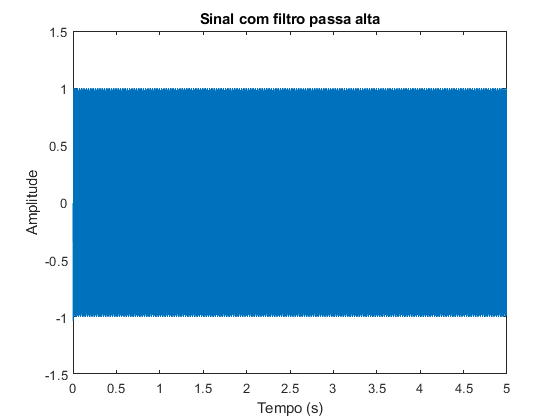

sa_highpass = filter(highpass_kaiser, sa);
%sound(sa_highpass, Fs)

figure;
plot(t, sa_highpass);
title('Sinal com filtro passa alta'); xlabel('Tempo (s)'); ylabel('Amplitude');

Sinal filtrado com filtro passa alta representado no domínio do tempo.

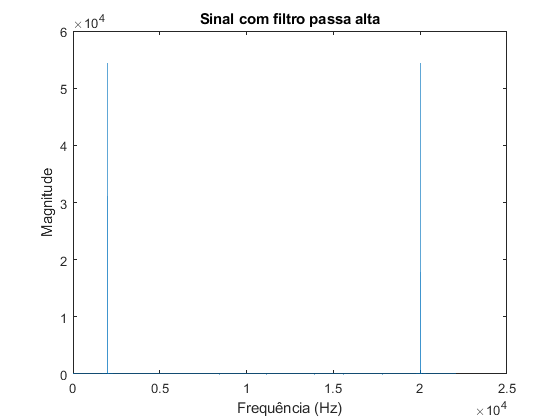

figure;
plot(f, abs(fft(sa_highpass)));
title('Sinal com filtro passa alta'); xlabel('Frequência (Hz)'); ylabel('Magnitude');

Sinal filtrado com filtro passa alta representado no domínio da frequência.

As frequências de passagem e atenuação para o caso do filtro passa alta foram, respectivamente: 1500Hz e 100Hz.

O filtro passa alta gerado é de ordem 80 e consegue atenuar com efeciência as frequências de 29Hz e 90Hz.

**Comparação do filtro FIR passa baixa filtro IRR passa baixa:**

Para compara o filtro passa baixa do tipo FIR gerado anteriomente se gerou um filtro IRR do tipo Butterworth, com as mesmas frequências de passagem e corte do filtro IRR, mesmas especificações de magnitude e especificação de ordem mínima.

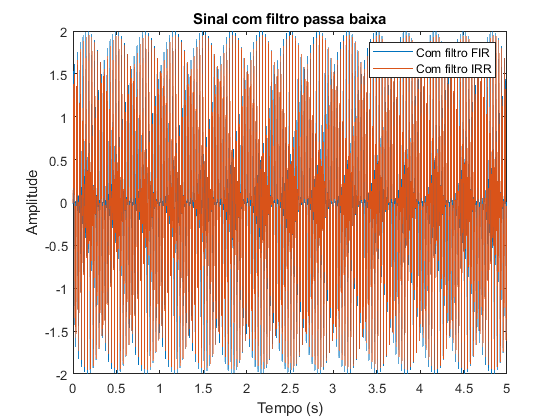

sa_irr_lowpass = filter(lowpass_butterworth, sa);
figure;
plot(t, sa_lowpass);
hold on;
plot(t, sa_irr_lowpass);
title('Sinal com filtro passa baixa'); xlabel('Tempo (s)'); ylabel('Amplitude');
legend('Com filtro FIR', 'Com filtro IRR');

Comparação do sinal filtrado com filtro passa baixa FIR o IRR no domínio do tempo.

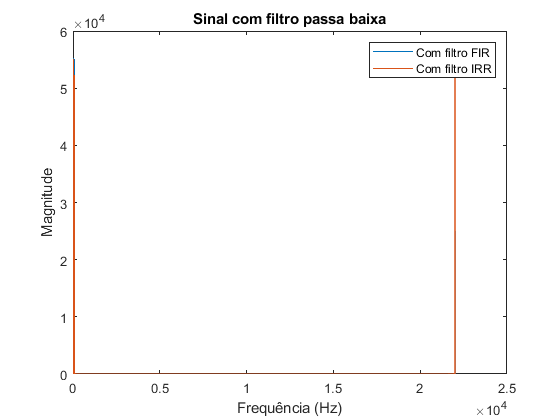

figure;
plot(f, abs(fft(sa_lowpass)));
hold on;
plot(f, abs(fft(sa_irr_lowpass)));
title('Sinal com filtro passa baixa'); xlabel('Frequência (Hz)'); ylabel('Magnitude');
legend('Com filtro FIR', 'Com filtro IRR');

Comparação do sinal filtrado com filtro passa baixa FIR o IRR no domínio da frequência.

Na resposta tempora se nota o atraso de grupo do filtro IRR, que faz com que o sinal filtrado por este sofra pequena defasagem. 

É possível notar que ambos os filtros conseguem atenuar a componente de alta frequência, porem, o filtro IRR gera uma pequena atenuação na componente de 90Hz, por estar muito perto da frequência de corte. O filtro IRR não apresenta esta característica.

É interessante notar, que mesmo utilizando a mínima ordem para ambos os filtro, o filtro FIR gerado foi de ordem 80 enquanto que o filtro IRR foi de ordem 4. Isso representa uma grande de diferença na necessidade de hardware para implementação. É possível concluir que o filtro IRR é muito mais fácil de ser implementado em um microcontrolador.

Segue a alocação de polos e zeros de cada filtro para provar a ordem gerada.

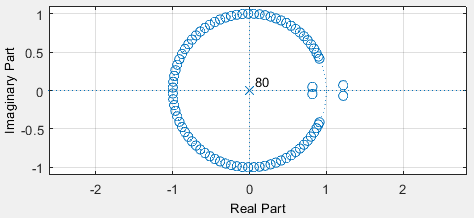

Alocação de polos e zeros do filtro passa baixa FIR

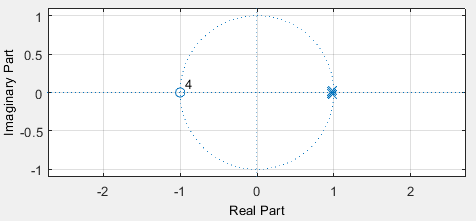

Alocação de polos e zeros do filtro passa baixa IRR